# **What is a 4-bar mechanism?**

A 4-bar mechanism is a type of mechanism used in engineering and mechanical design that consists of four rigid elements (bars or links) interconnected by joints. These joints allow the rods to move relative to each other, resulting in different configurations and movements.

# **What was the problem that inspired this project?**

Detailed motion analysis of a 4-bar mechanism can be complex and require advanced knowledge of kinematics and geometry. It can be challenging to understand and accurately model the kinematic behavior of the mechanism. Also the design of a 4-bar mechanism for a specific application may require the optimization of several parameters, such as the length of the bars and the location of the joints. The search for an optimal design that meets the performance requirements and constraints can pose challenges. For this reason, this program was developed to facilitate the development of a 4-bar mechanism with its respective lengths and movement conditions and also includes a physical part which can be performed with rapid prototyping to avoid any type of error at the time of final realization of the part.

# **Why is the four-bar mechanism important? **

The four-bar mechanism may seem a very simple mechanism but in reality it is very important so that anyone who wants or is designing robots, mechanisms should consider checking through this four-bar mechanism to see the types of mechanisms, their movements, speeds, accelerations that these may have and so in the future when they are making their own mechanism no longer have problems of possible failures through this allows us to have a clearer view on it.

Four-bar mechanisms are so important that we are surrounded by them not only in everyday life but also in industry and it is by means of four-bar mechanisms in combination with each other that more complex mechanisms can be constructed. In addition, four-bar mechanisms can directly generate a wide variety of movements (curves). For all this and for the economy in its construction, this type of mechanism is the most used in machines and can be found as mechanisms of door openings, vehicle suspensions, windshield wipers, forming part of the structure of machinery such as presses, excavators, conveyor machines, etc..

# **Why is the design of the four-bar mechanism important?**

This is very important when trying to produce a desired output motion for a specific input motion. In other words, in order to minimize cost and maximize efficiency, the designer must choose the type of machinery to be designed and select the lengths of the bars for the desired motion. All this can be achieved through dimensional synthesis, which involves carrying out an analysis to select the dimensions of the bars and the type of mechanism to be used.

# **What is the basis for determining the type of mechanism?**

It is based on Grashof's law which by means of the condition tells us that if the sum of the shortest and the longest link of a flat quadrilateral link is less than or equal to the sum of the two remaining links, then the shortest link can rotate completely with respect to a neighboring link. In other words, the condition is fulfilled if S + L ≤ P + Q, where S is the shortest link (according to the image corresponds to Side 3), L is the longest link (according to the image corresponds to Side 1 which in this case would come to be the fixed bar) and P and Q are the other links (according to the image corresponds to Side 2 and Side 4).

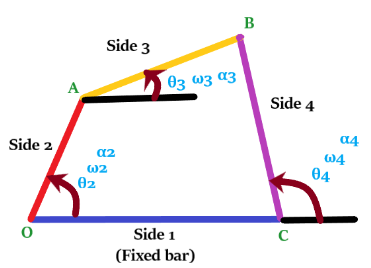

In a four-bar mechanism, if a bar makes a complete rotation, it is called a **crank**. If it performs a reciprocating motion, it is called a **rocker arm**. The connecting bar Side 3 is called a **coupler**.

The activity is going to be to change the dimensions of the four rods of the mechanism in the above construction so that:

- The mechanism has one crank and one rocker arm

- The mechanism has two rockers

- The mechanism has two cranks

Assuming the frame is horizontal, there are four possibilities for incoming and outgoing links:

- A crank: can rotate through a full 360 degrees

- One rocker: can rotate through a limited range of angles that does not include 0° or 180°.

- A 0 seesaw: can rotate through a limited range of angles that includes 0° but not 180°

- A π seesaw: can rotate through a limited range of angles including 180° but not 0°.

It should be noted that some authors do not distinguish between the types of seesaw.

# **How to start the program?**

In the Command Window, type the name of the program to run it.

PM4BA1

# **Arduino connection**

To establish the connection, the appropriate Arduino drivers need to be installed. Then, the following steps must be followed to connect the Arduino hardware and run the MATLAB application:

- In the Command Window, execute the following command:

arduinosetup

- A window will open in which you must select the connection method for your Arduino or module to be programmed.

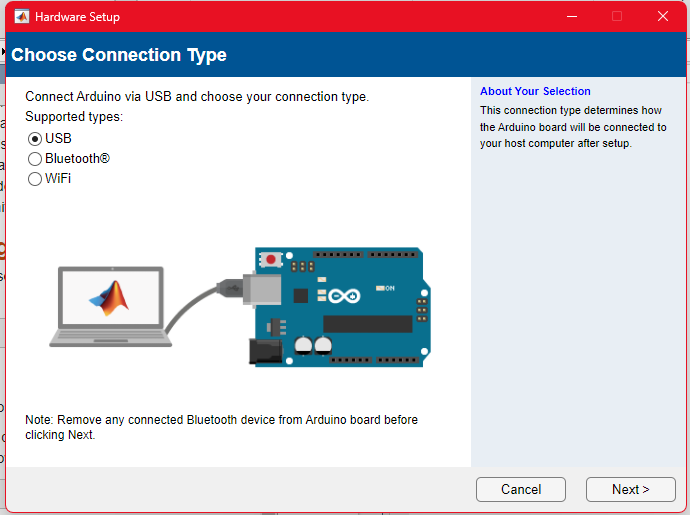

- After selecting the connection method, choose the board model and the port to which it is connected.

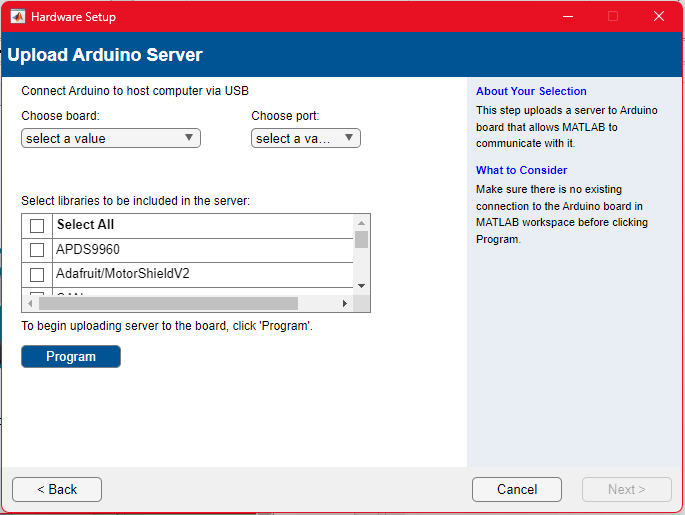

- Once you have selected all the parameters, you can proceed to program the board to start writing your code.

- If you select a wireless connection type, follow the steps indicated by the program.

If you need more information about the program, you can run the following code in the Command Window:

help arduino

# **Instructions for using the application **

Once the application is opened, it is recommended to run it in the following order because it was made to run sequentially

- Select the type of mechanism and in visual options place the option "View mechanism values"

- If you do not want the predefined values you can change their values and in case you enter wrong the program itself will give you a warning that you are making a mistake

-  After having followed the first two steps proceed to select in the order that the options are removed to be able to visualize your result once finished seeing all the options and want to see the results of the other mechanisms return to "Select the type of mechanism in this case the one that is second in the drop-down list" puts "View mechanism values" and again proceeds with the steps mentioned above.

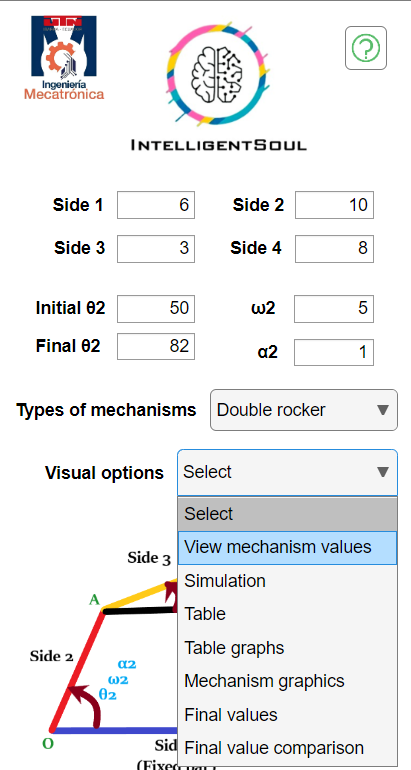

For the part of calculations with respect to the tables, it was carried out by applying the Jacobian matrix and its determinant, which is sometimes well known as "The Jacobian" since it provides us with the information of the point in which we want to compare and know about the behavior of the vectors near that point with which it is being taken as a reference, so that when there is a differentiable function, it automatically becomes invertible as long as its point is not zero, worse if the case occurs in which this function is not zero. invertible, so we must review, perhaps some data was entered incorrectly that makes it null.

As can be observed below, in the code lines, the use of the Jacobian results is maintained for the calculations that will be carried out later on for linear and angular velocities and accelerations, final angles and during the entire journey.

f1=a.*cos(t2)+b.*cos(t3)-c.*cos(t4)-d*cos(t1); %generation functions=0
f2=a.*sin(t2)+b.*sin(t3)-c.*sin(t4)-d*sin(t1); %generation functions=0

A=[-b.*sin(t3) c.*sin(t4);b.*cos(t3) -c.*cos(t4)];%THE JACOBIAN
B=-[a.*cos(t2)+b.*cos(t3)-c.*cos(t4)-d*cos(t1);
a.*sin(t2)+b.*sin(t3)-c.*sin(t4)-d*sin(t1)];

Ja=[-b*sin(t3) c*sin(t4);b*cos(t3) -c*cos(t4)];

The variable f1 is used to know the direction that the bars will have in the x-axis and f2 is used to know the direction that each bar will have in the y-axis and in the variables A and B the calculations of the Jacobian matrix are made to finally get the Jacobian in the variable Ja in the matrix.

The Jabonian matrix is used as a means to translate from one vector space to another and thus rely on Freudenstein's equations to be able to determine in a simpler way the real values of the angles and thus also be able to dimension our mechanism and see the lengths of our links.

Below is a small fragment of the calculations that apply this.

Aa=a*alfa2*(-sin(t2)+1i*cos(t2))-a*w2^2*(cos(t2)+1i*sin(t2));
Aax=-a*alfa2*sin(t2)-a*w2^2*cos(t2);
angB=atand(Vby/Vbx)+180;

the variable Aa is to calculate the linear acceleration at point A but as a resultant vector of its axes and Aax is the linear acceleration at point A but on the x-axis while angB is the angle which is calculated at that moment at point B.

And likewise, in order to display the final result in the table, the value that the user enters is placed in the calculation, as a part can be seen in the following line of code.

t2= app.Angle2_2.Value*pi/180

t2 is the angle of theta 2 and app.angle2_2 is the angle that the user entered or had already been predefined from the beginning to calculate the other values at its end point.

# **How does the animation work?**

The animation and graphic is a set of operations and calculations that allow us to show and detect where each of the bars will be and what angles or measures each of these will have. The first thing that is done is to detect if the data entered for each of the links are correct and comply with the "GRASHOF'S LAW", after using this law the necessary calculations are made to determine the measurements of the simulation and the mechanism such as its angular velocity, angular acceleration and its angles, then the 'EULER'S THEOREM' is used to obtain the positions of each of the links. Finally, the real and imaginary values are defined at the moment of graphing.

# **What is Grashof's law?**

Grashof's Law states that a four-bar mechanism has at least one joint of complete revolution if and only if the sum of the lengths of the shortest bar and the longest bar is less than or equal to the sum of the lengths of the remaining bars. It shall comply with the following:

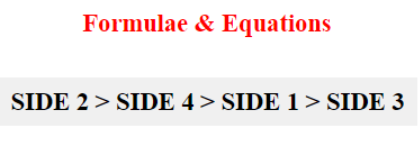

#### General Formula

#### **Crank -  Rocker**

**Double - Rocker**

# **What is Euler's theorem for?**

Euler's theorem is a system of calculations that allows us to identify where each one of our bars is in a Polar system, it is the important base of the simulation since it is in charge of showing each one of the links in its proper position, because otherwise they would be levitating in space without a defined position.

# **Is there any help, guide or tutorial on how to use the application?**

As it is an application for educational or work use, it has a section where we can get help in case of any failure when using the simulation or in the calculations. There is a button at the top right of the window, where you can find the most common failures and their possible solutions.

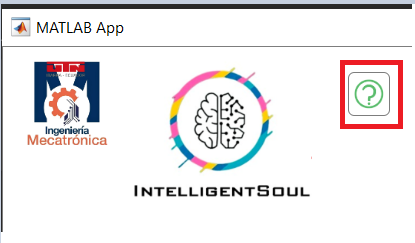

# **Does the programme tell me what mistakes I am making or may have made?**

If the program is designed to warn the user in case of making any type of error either in the entry of data such as links, angles, among others. If these functions are fulfilled, the programme will display a small window with an error number that will help us to find it in our help window, as we will see below:

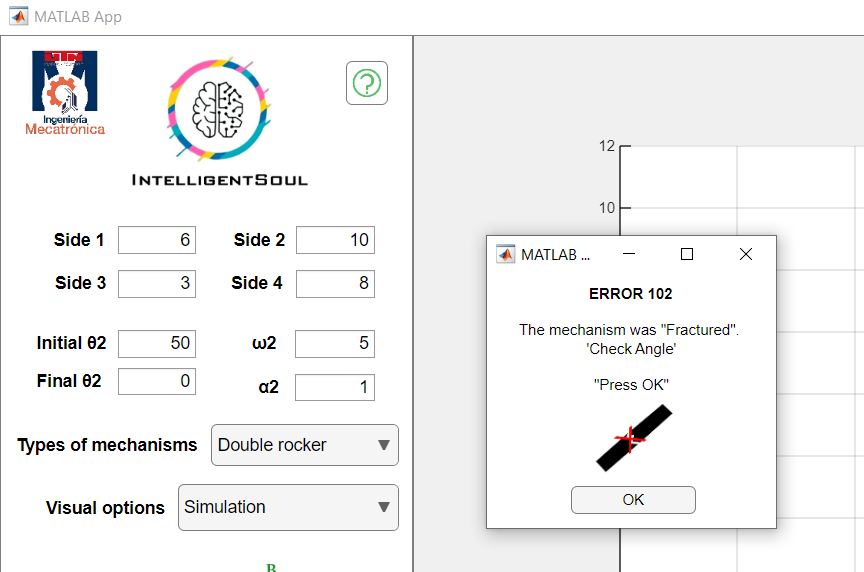

**In this part we can see the help window with the different errors that we may have:**

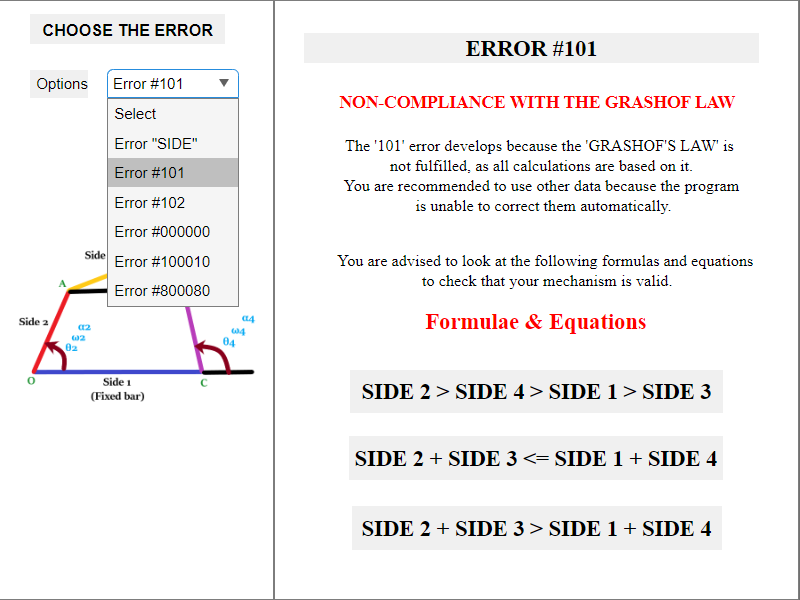

# **Is the programme capable of correcting any mistakes I have made or can it warn me?**

Of course it does, the program has a section of assumptions in which it will be executed at the beginning of all operations to determine if the data entered are correct, in case of seeing a data that does not agree with the mechanism, it will warn us where the possible error is and replace it with a '0'.

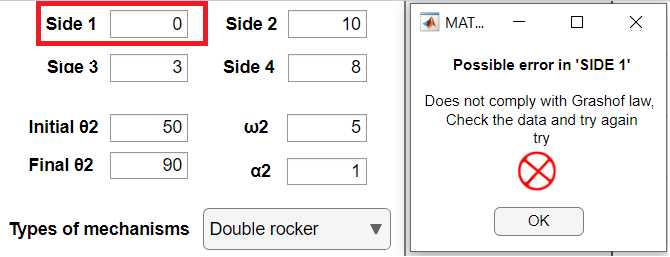

**It will also not warn us if we use a mechanism that is not appropriate for the data class and could generate an error when simulating the data class:**

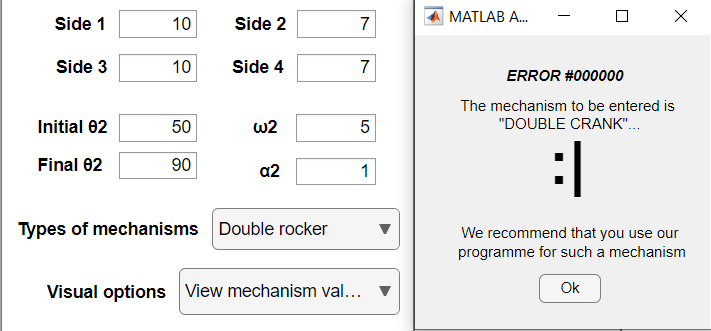

**It will also warn us if the mechanism fractures and this is because one of its angles is not adequate or the mechanism is not designed to reach those limits and fractures, in this case the application will inform us of this by setting a value of '0' in the angle that is possibly generating the 'Rupture' error.**

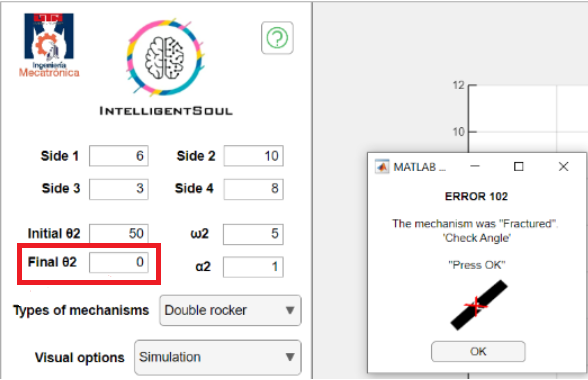

# **Finally the design of the help window with the logo and slogan of the work team.**